run('parse_sim_data');


## PLOTTER

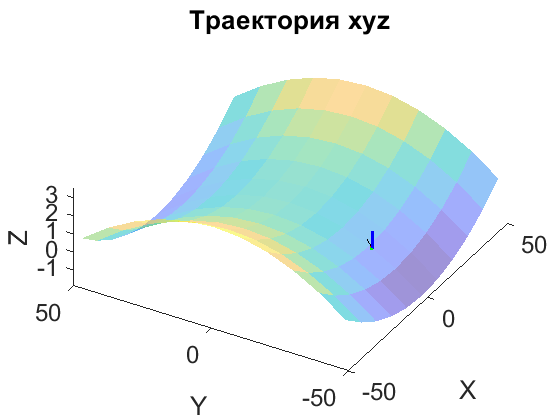

fs = 18;

%% xyz
figure
hold on
title('Траектория xyz')
m = max(max(abs(x_act)), max(abs(y_act)))*1.5 + 3 ;
d = 2*m/10;
[X,Y] = meshgrid(-m:d:m);  
xlabel('X')
ylabel('Y')
zlabel('Z')
Z = surf_fcn(X,Y);
surf(X,Y,Z, 'FaceAlpha',0.5, 'EdgeColor', 'None')
plot_frame(initial_r, initial_q)
plot3(act_states(1,:),act_states(2,:),act_states(3,:), 'k--');
set(gca,'FontSize',fs)
view(-60,60)

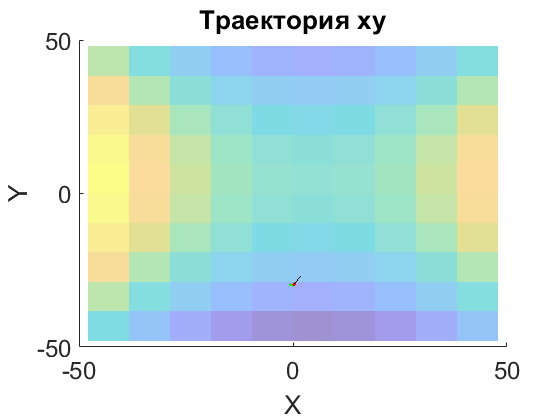


figure
hold on
title('Траектория xy')
m = max(max(abs(x_act)), max(abs(y_act)))*1.5 + 3 ;
d = 2*m/10;
[X,Y] = meshgrid(-m:d:m);  
xlabel('X')
ylabel('Y')
zlabel('Z')
Z = surf_fcn(X,Y);
surf(X,Y,Z, 'FaceAlpha',0.5, 'EdgeColor', 'None')
plot_frame(initial_r, initial_q)
plot3(act_states(1,:),act_states(2,:),act_states(3,:), 'k--');
set(gca,'FontSize',fs)
view(0, 90)

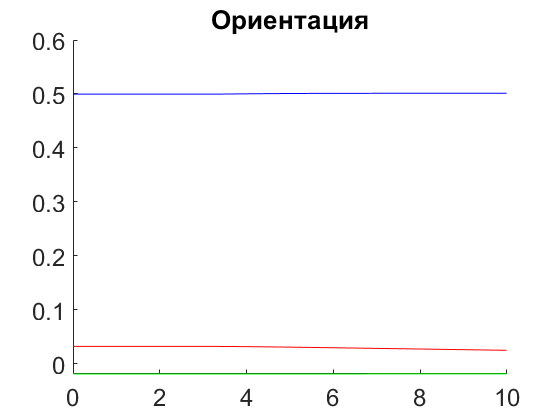


%% q
figure
hold on
title('Ориентация')
plot(timeline, qx_act, 'r')
plot(timeline, qz_act, 'b')
plot(timeline, qy_act, 'g')
set(gca,'FontSize',fs)

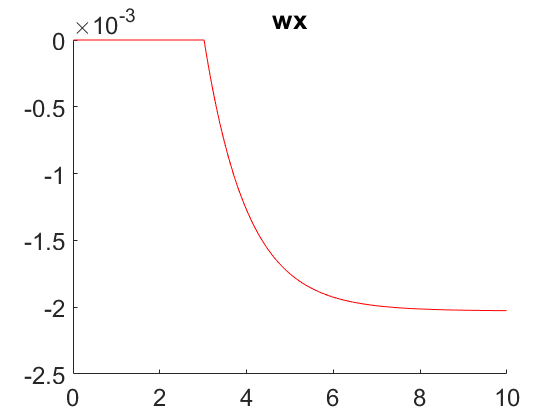


%% w
figure
hold on
title('wx')
plot(timeline, wx_act, 'r')
set(gca,'FontSize',fs)

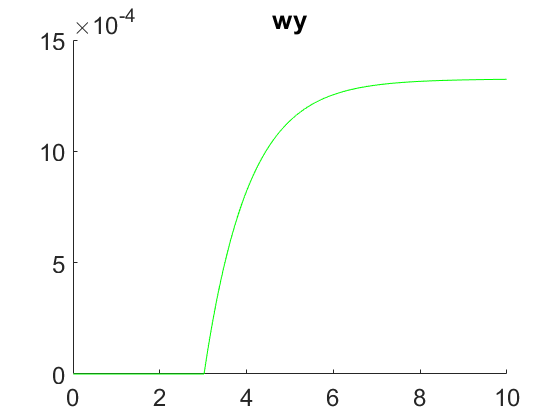


figure
hold on
title('wy')
plot(timeline, wy_act, 'g')
set(gca,'FontSize',fs)

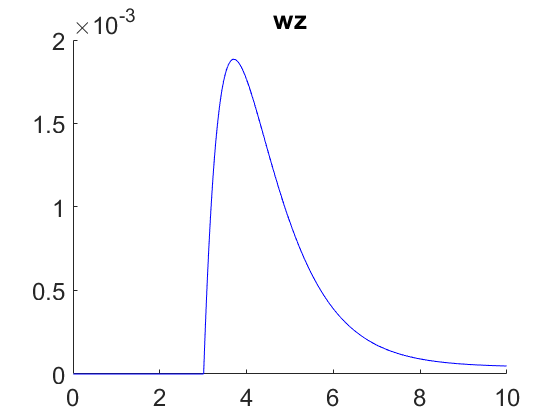


figure
hold on
title('wz')
plot(timeline, wz_act, 'b')
set(gca,'FontSize',fs)

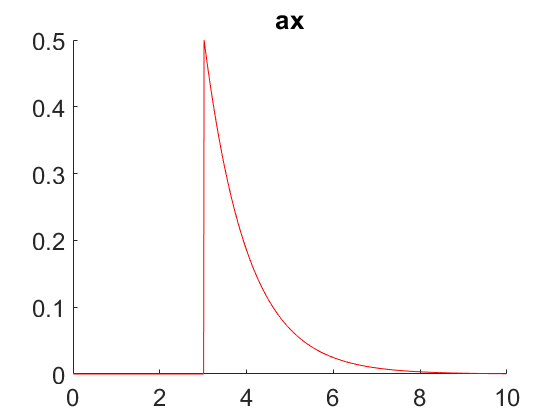


%% a
figure
hold on
title('ax')
plot(timeline, ax_act, 'r')
set(gca,'FontSize',fs)

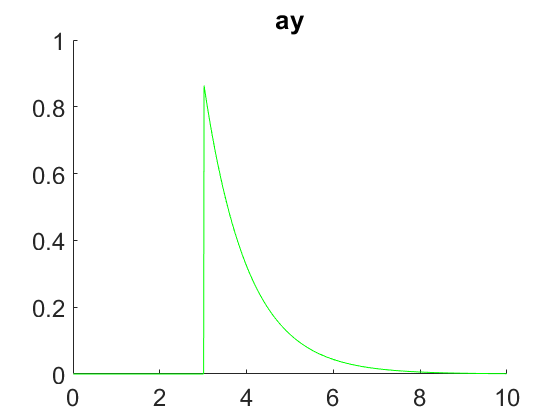


figure
hold on
title('ay')
plot(timeline, ay_act, 'g')
set(gca,'FontSize',fs)

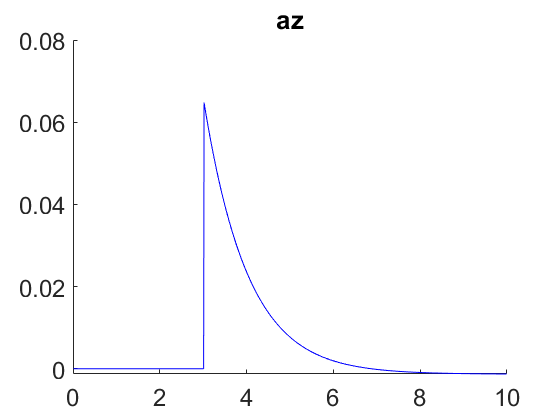


figure
hold on
title('az')
plot(timeline, az_act, 'b')
set(gca,'FontSize',fs)

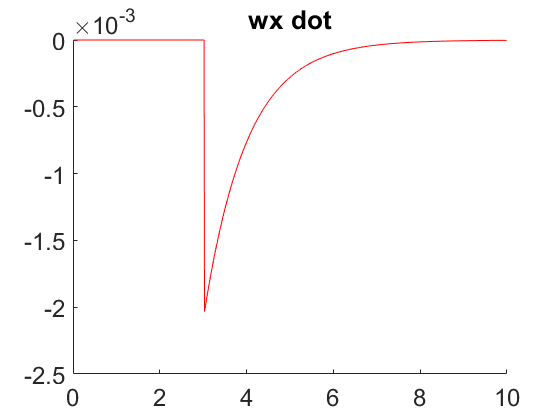


%% w_dot
figure
hold on
title('wx dot')
plot(timeline, wx_dot_act, 'r')
set(gca,'FontSize',fs)

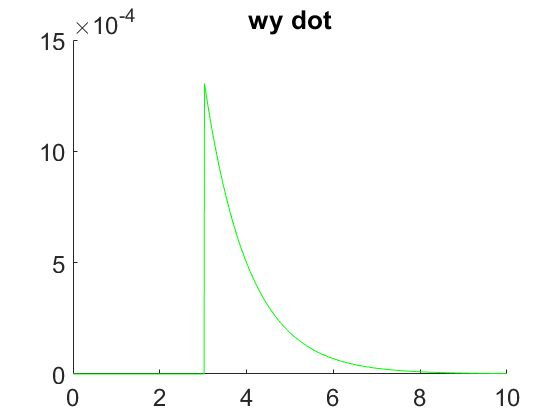


figure
hold on
title('wy dot')
plot(timeline, wy_dot_act, 'g')
set(gca,'FontSize',fs)

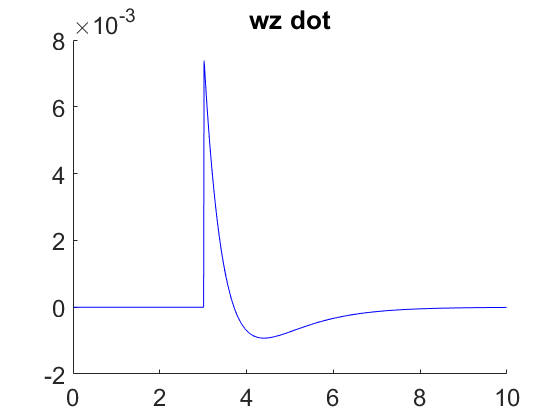


figure
hold on
title('wz dot')
plot(timeline, wz_dot_act, 'b')
set(gca,'FontSize',fs)